Logic:

People may not have "internalized" the impact of sample size on the precision of correlation estimates, and the consequences of small effect sizes on sample size requirements for powered studies.

Likewise, they may not have internalized even after reading Marek et al. and other work the impact of multivariate analyses and choices that yield larger effect sizes on power.

For example, an average effect size of r = 0.4 for multivariate analyses vs. 0.1 for univariate analyses is only a difference of 0.3. But the impact on sample size and power is enormous: A 16-fold difference in sample size requirements.

Marek et al. 2022 compare multivariate and univariate effect sizes (averaging effect sizes over the top 1% of univariate features).

Multivariate analyses show correlations on average about 4x larger than univariate effect sizes.

We can translate that difference into a difference in variance explained, power for a given sample size, and critical sample size needed.

mv = 0.4; % correlation
uv = 0.1; % correlation

var_ratio = 0.4^2 ./ (0.1^2)

var_ratio = 16

 Variance explained ratios are based on r^2. They are 16 times larger for multivariate analyses.

Power curves and sample size 

% Plot power curves
[ncritmv,pow,obspowmv] = power_calc(mv, .001, 200, 'r', [1 0 0], 0, 2);

One sample: d = 0.87, N needed 80% =  88 , N needed 50% =  58

2-group: d = 0.87, N per group 80% = 169 , N per group 50% = 108



[ncrituv,pow,obspowuv] = power_calc(uv, .001, 200, 'r', [.3 .7 1], 0, 2);

One sample: d = 0.20, N needed 80% = 1537 , N needed 50% = 953

2-group: d = 0.20, N per group 80% = Inf , N per group 50% = 1899



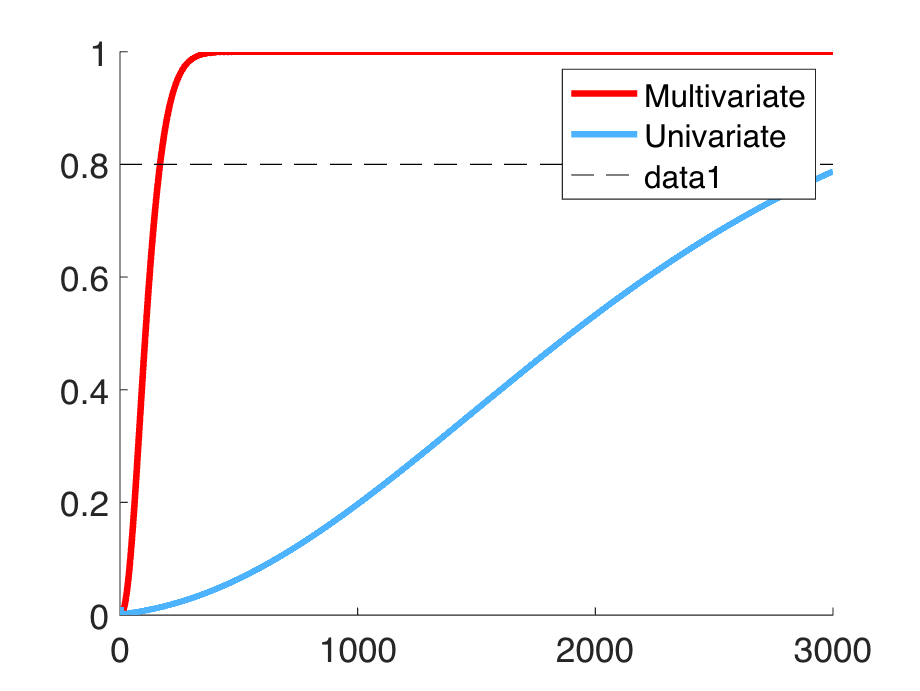


legend({'Multivariate' 'Univariate'})
hh = plot_horizontal_line(0.8); set(hh, 'LineStyle', '--');

The number needed for 80% power for one-sample association detection is n = 88 for multivariate, and n = 1537 for univariate. 

n_for_80_percent_power_ratio = ncrituv/ncritmv

n_for_80_percent_power_ratio = Inf

We need about 17 times as many participants for univariate tests.

obspowmv

obspowmv = 0.9985

obspowuv

obspowuv = 0.0437

With n = 200 as an arbitrary sample size, power with multivariate analysis is 99%, and power with univariate analysis is 4.4%.